# Derivative

## Definition

(SB) Let $(x_0, f(x_0))$ be a point on te graph of $y=f(x)$.

The **derivative** of $f$ at $x_0$ is  the slope of the tangent line to the graph of $f$ at $(x_0, f(x_0))$.

There are some common ways of denoting derivative of funtion $f$ at $x_0$:

- 
$$f'(x_0)$$


- 
$$\frac{df}{dx} (x_0)$$


- 
$$\frac{dy}{dx} (x_0)$$


- $f_x(x_0)$: this is popular in economics

We write this analyticaly as:


$$f'(x_0) = \lim_{h\rightarrow 0} \frac{f(x_0 + h) - f(x_0)}{h}$$


If this limit exists, then the function $f$ is **differentiable** at $x_0$.

## Derivative Example MPK

Let's consider a cobb-douglas production function again. 

If you own a firm, you would be very interested in how much additional output you can get from one more unit of capital of one more labor hired. If you know that, you can compare that against the cost of more capital and labor and determine if it is optimal to choose to increase capital and/or labor. 


$$U(K,L) = K^{\alpha} \cdot L^{1-\alpha}$$


Using the definition above, we will now compute derivative at different points. 

For now, let's fix capital. Suppose capital takes a long time to adjust, but labor can be adjusted. You currently have $K=1$ and $L=1$, what happens to output if you increase labor?

% fixed capital level
K = 1;
% current labor level
L = 1;

% Cobb Douglas Production Parameters
alpha = 0.5;
beta = 1-alpha;

% Output at x0
f_x0 = (K^alpha)*(L.^beta);

% a vector of h
h = linspace(0, 2, 50);

% output at f_x0_plus_h
x0_plus_h = L+h;
f_x0_plus_h = (K^alpha)*((x0_plus_h).^beta);

% derivatie 
f_prime_x0 = (f_x0_plus_h - f_x0)./h;

% Show Results in table
T = table(h', x0_plus_h', f_x0_plus_h', f_prime_x0');
T.Properties.VariableNames = {'h', 'x0_plus_h', 'f_x0_plus_h', 'f_prime_x0'};
T

T = 50×4 table
       h        x0_plus_h    f_x0_plus_h    f_prime_x0
    ________    _________    ___________    __________

           0          1             1            NaN  
    0.040816     1.0408        1.0202          0.495  
    0.081633     1.0816          1.04        0.49019  
     0.12245     1.1224        1.0595        0.48556  
     0.16327     1.1633        1.0785        0.48111  
     0.20408     1.2041        1.0973         0.4768  
      0.2449     1.2449        1.1157        0.47265  
     0.28571     1.2857        1.1339        0.46863  
     0.32653     1.3265        1.1518        0.46474  
     0.36735     1.3673        1.1693        0.46097  
     0.40816     1.4082        1.1867        0.45732  
     0.44898      1.449        1.2037        0.45377  
      0.4898     1.4898        1.2206        0.45033  
     0.53061     1.5306

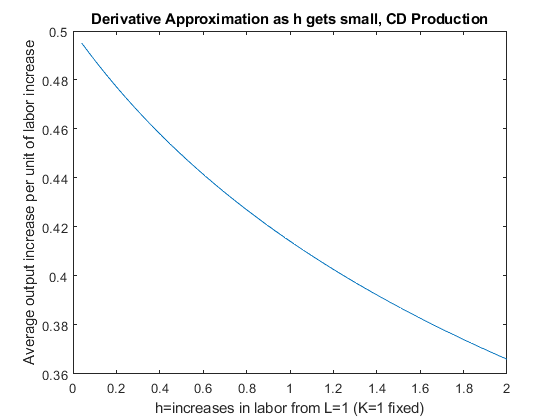


% Graph
close all;
figure();
plot(h, f_prime_x0)
ylabel('Average output increase per unit of labor increase')
xlabel('h=increases in labor from L=1 (K=1 fixed)')
title('Derivative Approximation as h gets small, CD Production')